# [Solutions] NRG: Impurity contribution to thermodynamic properties

Author: [Seung-Sup Lee](https://cqm.snu.ac.kr)

## Solution to Exercise (a): Complete the function for computing thermodynamic properties

The complete version of the function, `getTDconv.m`, is added under the `NRG` sub-directory. Compare with your version!

## Solution to Exercise (b): Single-impurity Kondo model

Perform the iterative diagonalization for the whole Kondo model (SIKM). For details of the iterative diagonalization for the SIKM, refer to the solution of the last tutorial.

clear

% Hamiltonian parameters
U = 4e-3; % Coulomb interaction at the impurity
epsd = -U/2; % impurity on-site energy
Delta0 = 2.5e-4; % hybridization strength
D = 1; % half-bandwidth
J = 8*Delta0/pi/U; % Kondo coupling strength
ozin = [-1;1]*D;
RhoV2in = [1;1];

% NRG parameters
Lambda = 2.5; % discretization parameter
N = 55; % length of the Wilson chain
Nkeep = 300;

% Wilson chain
N2 = 30;
[ff,~] = doCLD(ozin,RhoV2in,Lambda,N2);
% post-processing
ff = [ff;ff(end).*(Lambda.^(-(1:(N-numel(ff))).'/2))];
gg = zeros(size(ff));

% Construct local operators
[F,Z,S,I] = getLocalSpace('FermionS');
[Ss,Is] = getLocalSpace('Spin',1/2);

% particle number operator
NF = cat(3,contract(conj(F(:,:,1)),3,[1 3],F(:,:,1),3,[1 3]), ...
           contract(conj(F(:,:,2)),3,[1 3],F(:,:,2),3,[1 3]));

% ket tensor
A0 = getIdentity(Is,2,I,2,[1 3 2]);

% Impurity Hamiltonian
H0 = updateLeft(Ss,3,A0,permute(conj(S),[2 1 3]),3,A0);
% take the Hermitian conjugate to S
H0 = H0*(2*J);
H0 = H0 + gg(1)*updateLeft([],[],A0,sum(NF,3),2,A0);

% iterative diagonalization
Inrg = NRG_IterDiag (H0,A0,Lambda,ff(2:end),F,gg(2:end),sum(NF,3),Z,Nkeep);

22-10-16 03:35:00 | NRG: start
22-10-16 03:35:00 | #00/54 : NK=8/8, EK=0.07958/0.07958
22-10-16 03:35:00 | #01/54 : NK=32/32, EK=3.231/3.231
22-10-16 03:35:00 | #02/54 : NK=128/128, EK=6.466/6.466
22-10-16 03:35:00 | #03/54 : NK=300/512, EK=6.987/13.1
22-10-16 03:35:00 | #04/54 : NK=328/1200, EK=6.853/12.86
22-10-16 03:35:00 | #05/54 : NK=316/1312, EK=6.891/13.64
22-10-16 03:35:00 | #06/54 : NK=328/1264, EK=6.819/12.8
22-10-16 03:35:00 | #07/54 : NK=310/1312, EK=6.814/13.54
22-10-16 03:35:01 | #08/54 : NK=328/1240, EK=6.84/12.77
22-10-16 03:35:01 | #09/54 : NK=314/1312, EK=6.89/13.46
22-10-16 03:35:01 | #10/54 : NK=328/1256, EK=6.911/12.88
22-10-16 03:35:01 | #11/54 : NK=322/1312, EK=7.007/13.42
22-10-16 03:35:02 | #12/54 : NK=317/1288, EK=6.912/13.18
22-10-16 03:35:02 | #13/54 : NK=300/1268, EK=6.965/13.16
22-10-16 03:35:02 | #14/54 : NK=302/1200, EK=7.146/13.09
22-10-16 03:35:02 | #15/54 : NK=312/1208, EK=7.324/13.32
22-10-16 03:35:02 | #16/54 : NK=310/1248, EK=7.703/13.81
22-10-16 0

beta0 = 1; % parameter to define temperature values
[T,Tchi,Sent] = getTDconv(Inrg,S(:,:,2),beta0,Ss(:,:,2));

Perform the iterative diagonalization for the bath only. We replace the Kondo impurity with vacuum.

A0_2 = getIdentity(1,2,I,2); % numeric 1 for vaccum
H0_2 = gg(1)*updateLeft([],[],A0_2,sum(NF,3),2,A0_2);
Inrg2 = NRG_IterDiag (H0_2,A0_2,Lambda,ff(2:end),F,gg(2:end),sum(NF,3),Z,Nkeep);

22-10-16 03:35:14 | NRG: start
22-10-16 03:35:14 | #00/54 : NK=4/4, EK=0/0
22-10-16 03:35:14 | #01/54 : NK=16/16, EK=3.203/3.203
22-10-16 03:35:14 | #02/54 : NK=64/64, EK=6.15/6.15
22-10-16 03:35:14 | #03/54 : NK=256/256, EK=13/13
22-10-16 03:35:14 | #04/54 : NK=328/1024, EK=8.523/21.9
22-10-16 03:35:14 | #05/54 : NK=300/1312, EK=9.243/16.78
22-10-16 03:35:14 | #06/54 : NK=328/1200, EK=8.516/15.99
22-10-16 03:35:15 | #07/54 : NK=300/1312, EK=9.238/16.78
22-10-16 03:35:15 | #08/54 : NK=328/1200, EK=8.514/15.99
22-10-16 03:35:15 | #09/54 : NK=300/1312, EK=9.238/16.78
22-10-16 03:35:15 | #10/54 : NK=328/1200, EK=8.514/15.99
22-10-16 03:35:16 | #11/54 : NK=300/1312, EK=9.238/16.78
22-10-16 03:35:16 | #12/54 : NK=328/1200, EK=8.514/15.99
22-10-16 03:35:16 | #13/54 : NK=300/1312, EK=9.238/16.78
22-10-16 03:35:16 | #14/54 : NK=328/1200, EK=8.514/15.99
22-10-16 03:35:16 | #15/54 : NK=300/1312, EK=9.238/16.78
22-10-16 03:35:17 | #16/54 : NK=328/1200, EK=8.514/15.99
22-10-16 03:35:17 | #17/54 : 

[~,Tchi2,Sent2] = getTDconv(Inrg2,S(:,:,2),beta0);

Then subtract the thermodynamic properties from the bath only from those from the whole impurity model, to obtain the impurity contribution.

% impurity contribution to the spin susceptibility (* temperature)
Tchi_imp = Tchi - Tchi2; 
% impurity contribution to the entropy
Sent_imp = Sent - Sent2;

logT = log(T);
% impurity contribution to the specific heat C = T* dS/dT = dS / d(log T)
C_imp = interp1((logT(1:end-1)+logT(2:end))/2, ...
    diff(Sent_imp)./diff(logT),logT,'linear','extrap');

% Sommerfeld-Wilson ratio
WR = (Tchi_imp./C_imp)*(4*(pi^2)/3);

To rescale the temperature, we compute the Kondo temperature $T_\mathrm{K}$. Here we use the formula from the second-order poor man's scaling calculation.

% Kondo temperature
TK = sqrt(J) * exp(-1/J); % half-bandwidth D = 1
disp(TK);

   7.4500e-04



Plot the result.

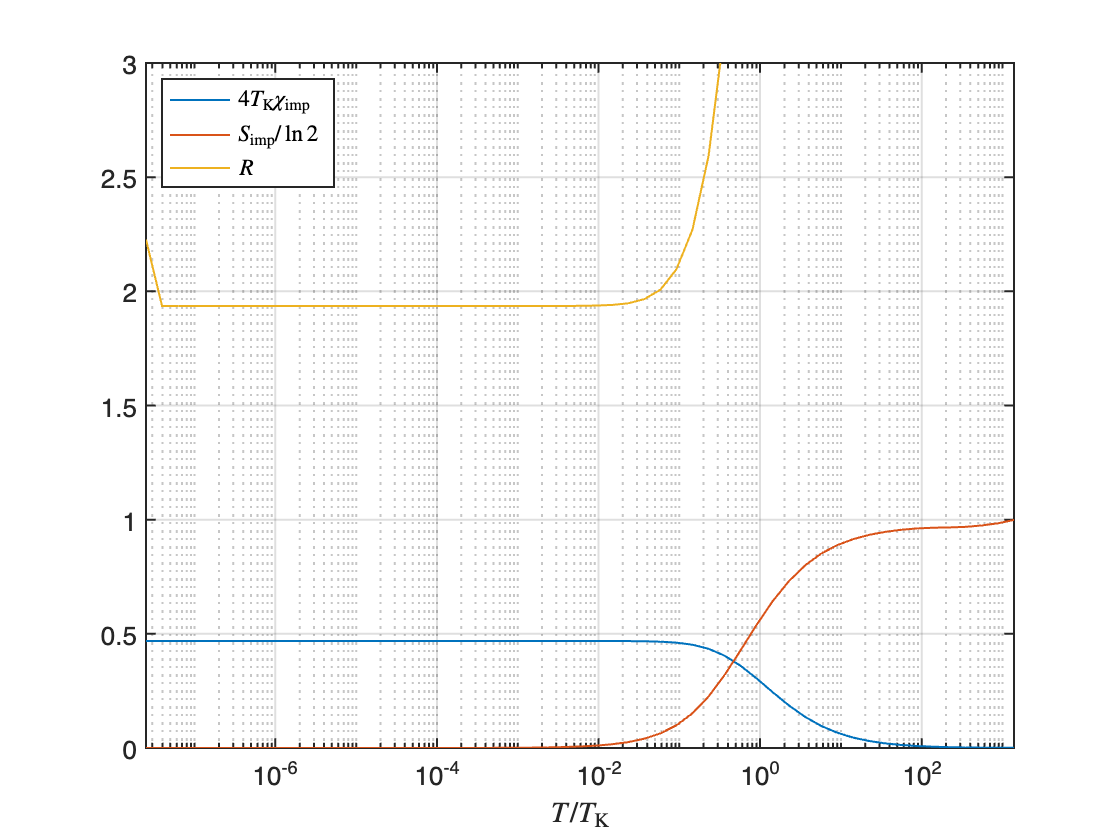

figure;
semilogx(T/TK,(Tchi_imp./T)*(4*TK), ...
    T/TK,Sent_imp/log(2), ...
    T/TK,WR,'LineWidth',1);
set(gca,'LineWidth',1,'FontSize',13);
xlabel('$T / T_\mathrm{K}$','Interpreter','latex');
legend({'$4 T_\mathrm{K} \chi_\mathrm{imp}$'; ...
    '$S_\mathrm{imp} / \ln 2$'; ...
    '$R$'}, ...
    'Interpreter','latex','Location','northwest');
ylim([0 3]);
xlim([min(T) max(T)]/TK);
grid on;

The curves of $R(T)$ and $\chi_\mathrm{imp}(T)$ for the SIKM exhibit similar behavior as those for the SIAM. Compare this plot with the demonstration plot. The kinks of $R$ at the highest and the lowest temperatures come from numerical artifact.

On the other hand, the curve of $S_\mathrm{imp}(T)$ for the SIKM shows different features from that for the SIAM. $S_\mathrm{imp} (T)$ for the SIAM has had three plateaus that represent three regimes: (i) $\ln 4$ for the free orbital regime, (ii) $\ln 2$ for the local moment regime, and (iii) $0$ for the strong coupling regime. $S_\mathrm{imp} (T)$ for the SIKM has only two plateaus: (i) $\ln 2$ for the local moment regime and (ii) $0$ for the strong coupling regime.

The absence of the free orbital regime is natural. In the derivation of the SIKM out of the SIAM, the doubly-occupied and the empty states of the impurity are "integrated out." As the result, the impurity of the SIKM has only spin degrees of freedom. That is, there is no free orbital regime at all for the SIKM.